# Landscape

## The equations

## 
$$g(X,Q) = \sum_j \|X-Y_jQ_j\|^2 
\\
f(X) = \min_{Q} g(X,Q)
\\
\nabla g(X,Q) = 2\bigg(\sum_j(X-Y_jQ_j), Y^\top(YQ-X)\bigg)
\\
\nabla^2 g(X,Q)[U,V] = \nabla g(U,V)$$


## Slices

seed=randi(100,1) %38

seed = 64

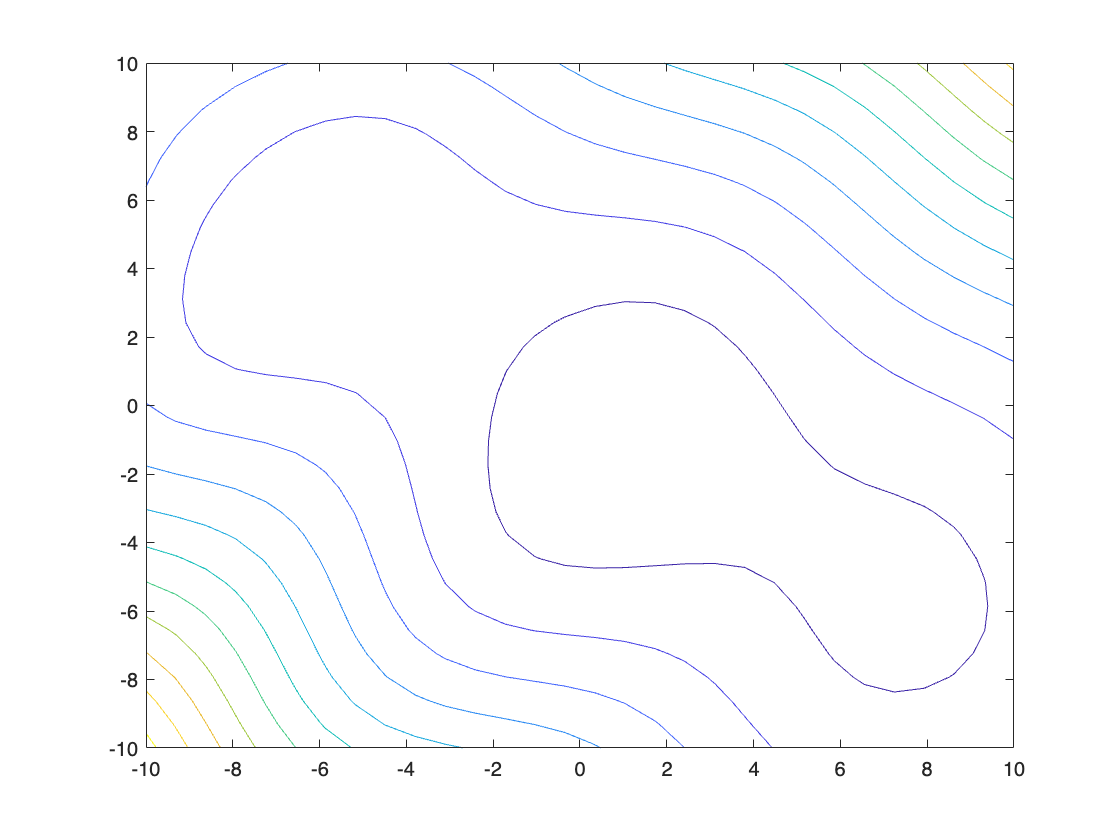

rng(seed)
n=3; % data dimension
k=1; % number of matrices
p=n-1; % size of factorization X of barycenter B
r=n-1; % size of factorization Y of data A
A = data(n,k,r);
prob = nonconvex_problem(A,r,p);
t = linspace(-10,10,30);
costs = surfprofile(prob,[],[],[],t,t);
contour(t, t, costs.')

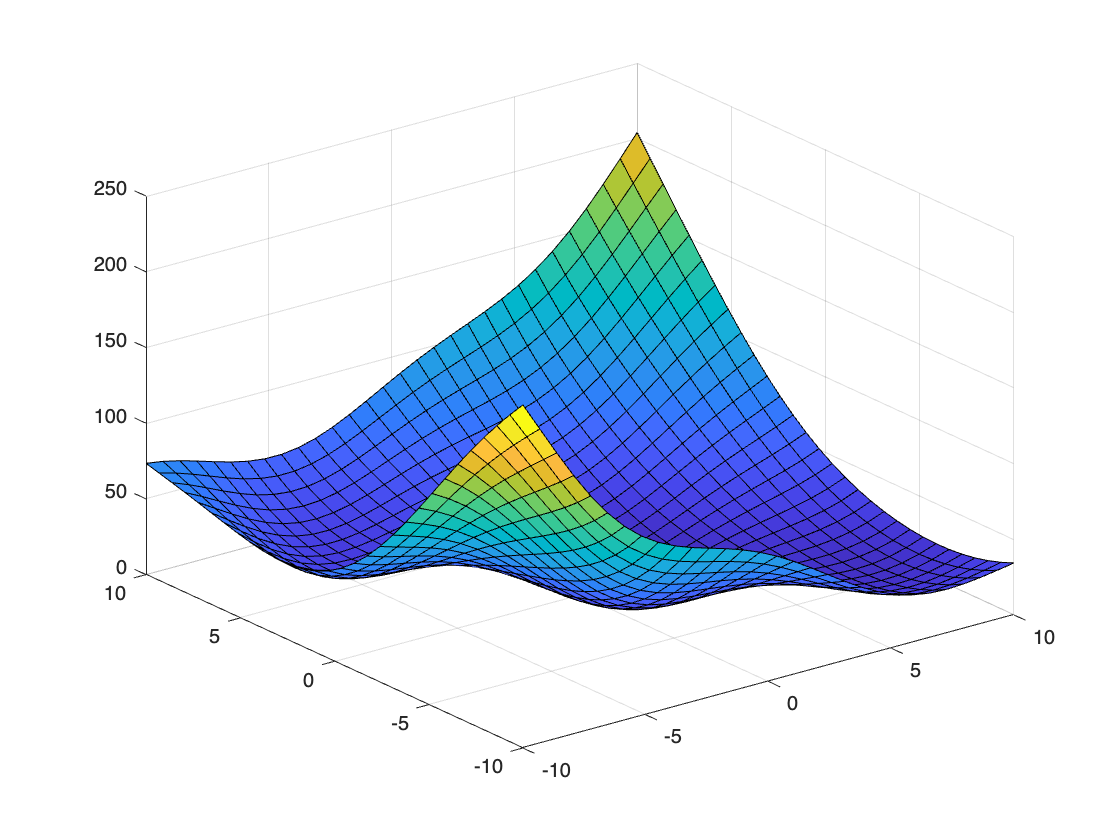

surf(t, t, costs.')

## Dependance to the initialization

clear
n=5; % data dimension
k=5; % number of matrices
r=round(n/2); % size of factorization Y of data A
p=r+1; % size of factorization X of barycenter B
A = data(n,k,r);
% Amean = mean(A,3);
% x0.X = sqrt(Amean);
prob = nonconvex_problem(A,r,p);
niter=5;
X = zeros(n,p,niter);
options.verbosity=0;
for j=1:niter
    x = trustregions(prob,[],options);
    X(:,:,j) = x.X;
end
Bs = pagemtimes(X, multitransp(X));
Bmean = sum(Bs,3)/niter
Bstd = norm(Bmean-Bs,"fro")/(niter-1);
Bstd_relative = Bstd/norm(Bmean,"fro")